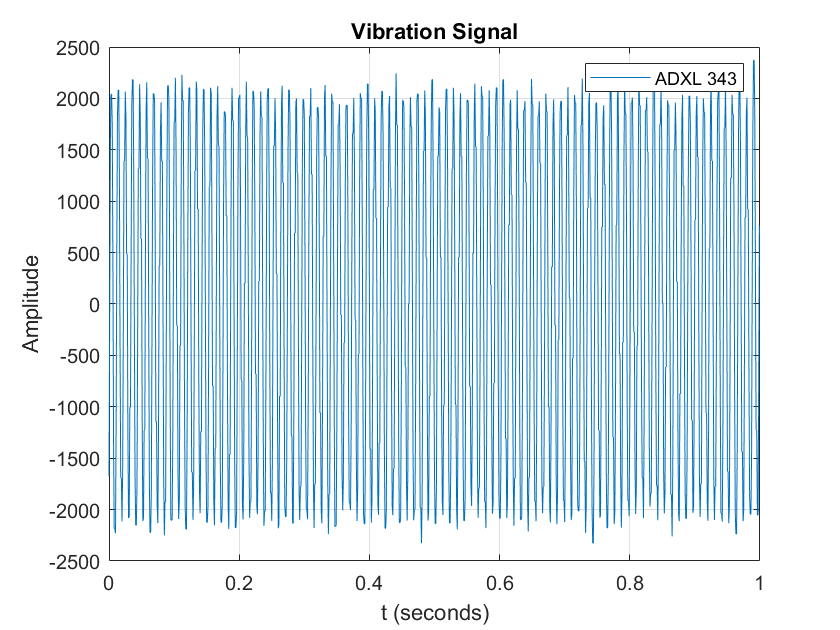

Fs = 1000;          % Sampling frequency (100 kHz)                   
T = 1/Fs;             % Sampling period       
t = 0:T:1-T;        % Time vector

plot(t,mpu6050)
% semilogy(t,ceramic, t,foil)
% yticks([0.1 0.2 1.5])
legend('ADXL 343');
title('Vibration Signal')
xlabel('t (seconds)')
ylabel('Amplitude')
grid on

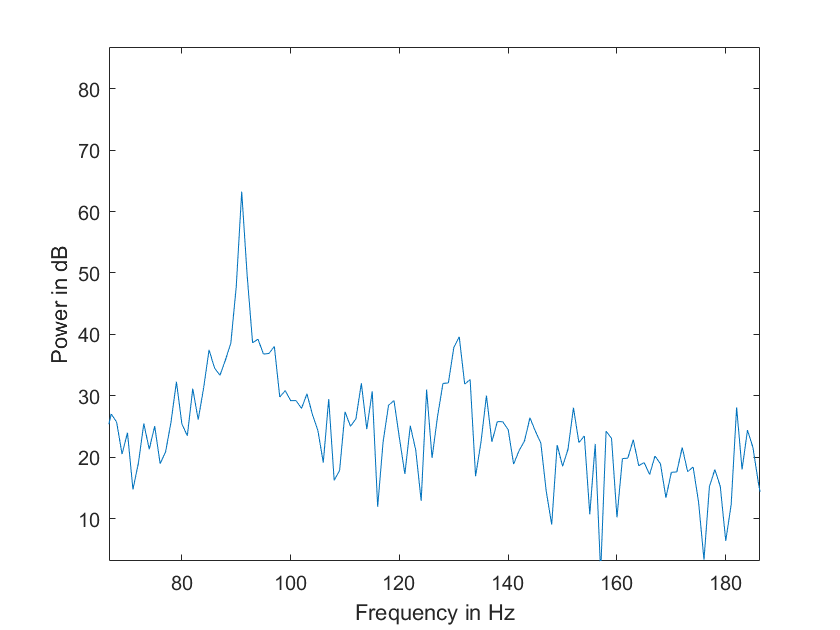


NFFT = length(mpu6050); %length of the Signal (FFT Signal Points)
[P,F] = periodogram(mpu6050,[],NFFT,Fs,'power');

plot (F,10*log10(P));
xlabel('Frequency in Hz')
ylabel ('Power in dB')

xlim([66.6 186.3])
ylim([3.1 86.8])